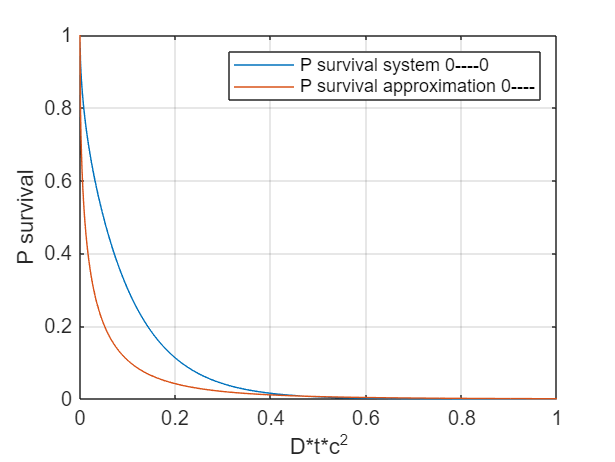

clc
clear
maxn = 100; %Iteration maximum for direct calculation
P_survival_direct = 0; %Set to zero before iteration
Dtc2 = linspace(0,1,1000); %Linspace DtC2

for n = 0:maxn-1 
    P_survival_direct = P_survival_direct + 8./((2*(n+1)-1).^2 * pi^2) .* exp(-(2*(n+1)-1).^2 * pi^2 .* Dtc2);
end

P_survival_approx = exp(-4*sqrt(pi)*sqrt(Dtc2)); %approximate equation for comp.

%Plot the two equations together.
plot(Dtc2, P_survival_direct, 'DisplayName', 'P survival system 0----0');
hold on;
plot(Dtc2, P_survival_approx, 'DisplayName', 'P survival approximation 0----');
hold off; 

xlabel('D*t*c^2');
ylabel('P survival');
grid on;
legend;




syms s t %Symbolic variables. 

% constants
D_3d=1e-1;
r_int=3e-3;
k_on=1e4;
l_DNA=1e3;
K_0 = besselk(0,sqrt(s / D_3d) * r_int); %Modified Bessel functions of the second kind
K_1 = besselk(1,sqrt(s / D_3d) * r_int); %Modified Bessel functions of the second kind
K_0_s = @(s) K_0

K_0_s = function_handle with value:
    @(s)K_0


K_1_s = @(s) K_1

K_1_s = function_handle with value:
    @(s)K_1




% Define the function in the Laplace domain
F_s = (k_on * l_DNA / s^2) * (1 + (k_on * K_0) / (2 * pi * sqrt(s / D_3d) * r_int * K_1))^(-1);

% Perform numerical inverse Laplace transform using ilaplace (symbolic method)
f_t_sym = ilaplace(F_s, s, t);
disp('Inverse Laplace Transform (Symbolic):');

Inverse Laplace Transform (Symbolic):


disp(f_t_sym);

$$10000000\,\mathrm{ilaplace}\left(\frac{1}{s^{2}\,\left(\frac{500000\,\sqrt{10}\,K_{0}\left(\frac{3\,\sqrt{10\,s}}{1000}\right)}{3\,\sqrt{s}\,\pi \,K_{1}\left(\frac{3\,\sqrt{10\,s}}{1000}\right)}+1\right)},s,t\right)$$

clear s t
% Numerical approach using Talbot's method
t_vals = 10.^(-16:.05:2); % Define time points
F_s_fun = @(s) F_s

F_s_fun = function_handle with value:
    @(s)F_s


Test = @(t) Talbot(F_s_fun,t,8)

Test = function_handle with value:
    @(t)Talbot(F_s_fun,t,8)



K0= @(s) besselk(0,sqrt(s / D_3d) * r_int);
K_1_div_K_0 = @(s) (sqrt(s / D_3d) * r_int).*besselk(1,sqrt(s / D_3d) * r_int)./K0;
%K_1_div_K_0(K0==0)=x(K0==0);

F_s_fun2 = @(s) (k_on * l_DNA / s^2) * (1 + (k_on) / (2 * pi * sqrt(s / D_3d) * r_int * K_1_div_K_0))^(-1);
disp("test 2")

test 2


Test2 = @(t) Talbot(F_s_fun2,t,8)

Test2 = function_handle with value:
    @(t)Talbot(F_s_fun2,t,8)


disp("test(1)")

test(1)


Test(1)

$$ans = \begin{array}{l} \frac{2\,\mathrm{real}\left(\frac{\frac{79293835279355390625}{4398046511104}-\frac{655349401490476484375}{140737488355328}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{2\,\mathrm{real}\left(\frac{\frac{50069020281838359375}{4398046511104}+\frac{472242407555922578125}{2199023255552}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{2\,\mathrm{real}\left(\frac{\frac{417045469476189921875}{562949953421312}+\frac{566054048208270234375}{281474976710656}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{2\,\mathrm{real}\left(\frac{-\frac{46853534160517421875}{590295810358705651712}-\frac{467819326536612578125}{4722366482869645213696}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{2\,\mathrm{real}\left(\frac{-\frac{101124074911406796875}{8796093022208}-\frac{143516645675965390625}{2199023255552}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{2\,\mathrm{real}\left(\frac{-\frac{490577526637552734375}{18014398509481984}+\frac{260070647364113359375}{18014398509481984}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{2\,\mathrm{real}\left(\frac{-\frac{155355024630714296875}{1099511627776}+\frac{136825172340861328125}{8796093022208}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{26973802210487578125\,\mathrm{real}\left(\frac{1}{\sigma_{1}}\right)}{549755813888}\\ \mathrm{where}\\ \sigma_{1}=s^{2}\,\left(\frac{500000\,\sqrt{10}\,K_{0}\left(\sigma_{2}\right)}{3\,\sqrt{s}\,\pi \,K_{1}\left(\sigma_{2}\right)}+1\right)\\ \sigma_{2}=\frac{3\,\sqrt{10}\,\sqrt{s}}{1000} \end{array}$$

disp("Test(2)")

Test(2)


Test(2)

$$ans = \begin{array}{l} \frac{\mathrm{real}\left(\frac{\frac{79293835279355390625}{4398046511104}-\frac{655349401490476484375}{140737488355328}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{\mathrm{real}\left(\frac{\frac{50069020281838359375}{4398046511104}+\frac{472242407555922578125}{2199023255552}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{\mathrm{real}\left(\frac{\frac{417045469476189921875}{562949953421312}+\frac{566054048208270234375}{281474976710656}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{\mathrm{real}\left(\frac{-\frac{46853534160517421875}{590295810358705651712}-\frac{467819326536612578125}{4722366482869645213696}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{\mathrm{real}\left(\frac{-\frac{101124074911406796875}{8796093022208}-\frac{143516645675965390625}{2199023255552}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{\mathrm{real}\left(\frac{-\frac{490577526637552734375}{18014398509481984}+\frac{260070647364113359375}{18014398509481984}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{\mathrm{real}\left(\frac{-\frac{155355024630714296875}{1099511627776}+\frac{136825172340861328125}{8796093022208}\,\mathrm{i}}{\sigma_{1}}\right)}{5}+\frac{26973802210487578125\,\mathrm{real}\left(\frac{1}{\sigma_{1}}\right)}{1099511627776}\\ \mathrm{where}\\ \sigma_{1}=s^{2}\,\left(\frac{500000\,\sqrt{10}\,K_{0}\left(\sigma_{2}\right)}{3\,\sqrt{s}\,\pi \,K_{1}\left(\sigma_{2}\right)}+1\right)\\ \sigma_{2}=\frac{3\,\sqrt{10}\,\sqrt{s}}{1000} \end{array}$$

f_t_vals = arrayfun(Test, t_vals);

% Plot the numerical inverse Laplace transform
%figure;
%plot(t_vals, f_t_vals, 'r', 'LineWidth', 2);
%xlabel('Time t');
%ylabel('f(t)');
%title('Numerical Inverse Laplace Transform');
%grid on;

